clear
clc
close all

Parámetros

m_movil = 0.94; % [kg] Masa plato + bobina
m_cubesat = 1.33; %[kg] Masa Cubesat
m_total = m_movil + m_cubesat;
bm = 1000; % [Ns/m] coeficiente de fricción viscosa (a confirmar)
K_motor = 51.6; %[N/A] [Vs/m] constante de back EMF y de fuerza (valen lo mismo)
g = 9.81; %[m/s^2] Aceleración de la gravedad

R = 3; %[Ohm] Resistencia del bobinado
L = 1.9e-3; %[H] Inductancia del bobinado (medida a 1000Hz)

Pot_max = 75 ; %[W] Potencia máxima
I_max = sqrt(Pot_max/R); % [A]
V_max = sqrt(Pot_max*R); % [V]

K_motor_virtual = K_motor;
bm_virtual = bm;
m_total_virtual = m_total;

Espacio de Estados

%[x
% x' 
% i]

A = [0 1 0;
    0 -bm/m_total K_motor/m_total;
    0 -K_motor/L -R/L];
Bu = [0 ; 0 ; 1/L];
Bd = [0; -1/m_total ; 0];
C = [1 0 0;
     0 -bm/m_total K_motor/m_total];
Du = [0;0];
Dd = [0;-1/m_total];

sys_c = ss(A,Bu,C,Du);
sys_per = ss(A,Bd,C,Dd);

Hc = tf(sys_c)

Hc =
 
  From input to output...
                1.196e04
   1:  ---------------------------
       s^3 + 5984 s^2 + 7.573e06 s
 
             1.196e04 s
   2:  -----------------------
       s^2 + 5984 s + 7.573e06
 
Continuous-time transfer function.



Hd = tf(sys_per)

Hd =
 
  From input to output...
            -0.4405 s - 695.6
   1:  ---------------------------
       s^3 + 5984 s^2 + 7.573e06 s
 
        -0.4405 s^2 - 695.6 s
   2:  -----------------------
       s^2 + 5984 s + 7.573e06
 
Continuous-time transfer function.



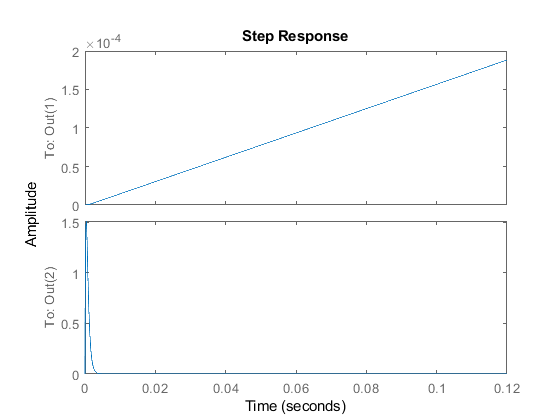


step(sys_c)

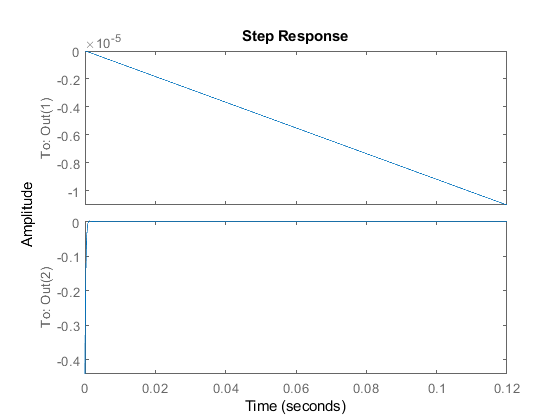

step(sys_per)

Controlabilidad

Cont = rank([Bu A*Bu A*A*Bu])

Cont = 3

Es controlable desde la entrada de voltaje V

Control proporcional de corriente

wc_corr = 5000; %Frecuencia de corte
R_control = wc_corr * L;


PID en cascada

zita = 0.7;
wp = 10;

ba = m_total_virtual*(2*zita+1)*wp

ba = 54.4800

ksi = m_total_virtual*(2*zita+1)*wp^2

ksi = 544.8000

ksia = m_total_virtual*wp^3

ksia = 2270